vid=VideoReader("PulsVid.mp4");
fil = load("PulsData.txt");
fil=fil-mean(fil);
R=transpose(fil(:,1));
G=transpose(fil(:,2));
B=transpose(fil(:,3));
R=R-mean(R);
G=G-mean(G);
B=B-mean(B);

fps=vid.FrameRate;
N=length(R);
t=0:1/fps:(N-1)/fps;

N_fft=2^(14);
df=fps/N_fft

df = 6.1035e-04

f=(-fps/2:df:fps/2-df)*60;
R_fft=fftshift(fft(R,N_fft));

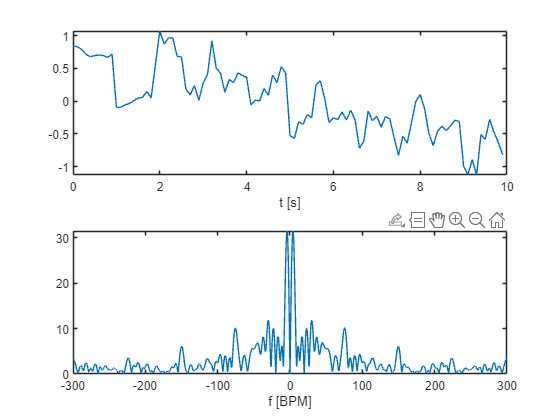

figure;

subplot(2,1,1);
plot(t,R);
xlabel("t [s]");

subplot(2,1,2);
plot(f,abs(R_fft));
xlabel("f [BPM]");